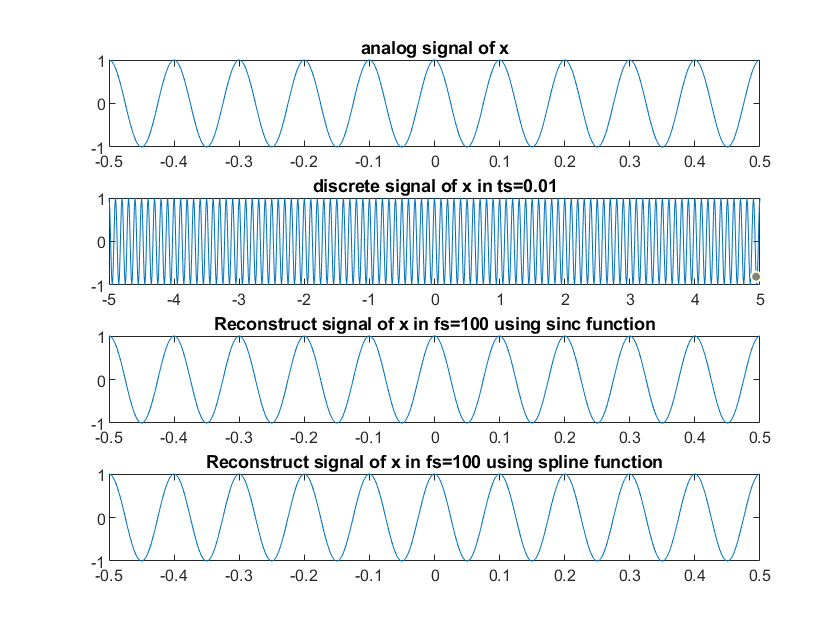

t=-0.5:0.001:0.5;
xa=cos(20*pi*t);
subplot(4,1,1)
plot(t,xa)
title('analog signal of x')
% prb 3.17.1
ts=0.01;
fs=1/ts;
% ts=0.05;
% ts=0.1;
n=-500:500;
xd=cos(20*pi*ts*n);
subplot(4,1,2)
plot(n*ts,xd)
title(strcat('discrete signal of x in ts= ',num2str(ts)))

% prb 3.17.2
yrs=xd*sinc(fs*(ones(length(n),1)*t-(ts*n)'*ones(1,length(t))));

subplot(4,1,3)
plot(t,ya)
title(strcat('Reconstruct signal of x in fs= ',num2str(1/ts),' using sinc function'))


% prb 3.17.3
yrsp=spline(n*ts,xd,t);
subplot(4,1,4)
plot(t,yrsp)
title(strcat('Reconstruct signal of x in fs= ',num2str(1/ts),' using spline function'))